# Compress Deep Learning Models, Generate Code, and Profile Performance

Note: This chapter has to be adapted to the models trained in the previous chapter. They can be found in the models directory.

This exercise requires **Deep Learning Toolbox Model Quantization Library, MATLAB Coder Interface for Deep Learning, **and **Visual Studio C++ Compiler** (check `mex -setup C++`).

Exercise 3 covers a three-part workflow to optimize deep learning models for deployment. Initially, you will apply the **projection** technique to compress a deep learning model, reducing its size while aiming to retain its accuracy. Following the compression, you will use Simulink to generate C code for both the original and compressed models. The final part involves performance profiling, where you will compare the execution time of the generated code for both models, providing insights into the efficiency improvements achieved through model compression. This exercise is designed to equip you with practical skills in model optimization, code generation, and performance analysis, essential for deploying efficient deep learning models in real-world applications.

## Load Previously Trained LSTM Network

clear
addpath(fullfile("../data"))
addpath(fullfile("../models"))
addpath(fullfile("../helpers"))

load("LSTM.mat");
net.Layers
analyzeNetwork(net)

Note that the original LSTM network has 450.1k learnables. By default, in MATLAB, DL network learnables are stored in single-precision, floating-point format (fp32). At 4 bytes (32 bits) per learnable, this translates to a total learnables size of **~1.8 MB**. 

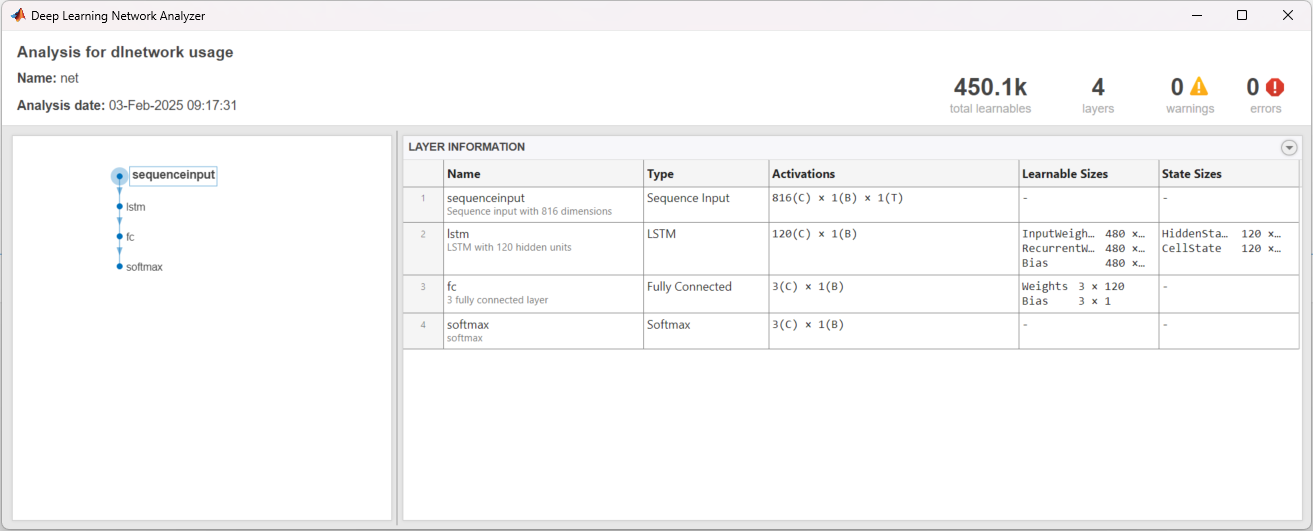

## Data Preparation

%load the data...
load("LSTM_data_preprocessed.mat")
load("ECG_Data_split.mat")

## Model Compression - Projection

### Understanding network compression with projection

To compress a neural network, MATLAB uses a technique that involves projecting the network's layers into smaller parameter subspaces, thereby reducing the memory footprint of the model. This is done by introducing projector matrices that transform the learnable parameters into a lower-dimensional space without significantly compromising prediction accuracy. A projected deep neural network can also exhibit faster forward passes (inference) or deployed to embedded hardware using library-free C or C++ code generation, making projection a powerful technique for both reducing memory requirements and boosting throughput. To learn more about the algorithm based on principal component analysis (PCA) underlying network projection, refer to [this page](https://www.mathworks.com/company/newsletters/articles/compressing-neural-networks-using-network-projection.html).

As of R2024a, the following network layers support compression with projection:

- convolution2dLayer

- fullyConnectedLayer

- lstmLayer

- gruLayer

### Explore Compression Levels

A trade-off exists between the amount of compression we apply to the network and its accuracy. In general, reducing the number of learnable parameters in a pretrained network will reduce its accuracy. Let's experiment by compressing the network with projection by a range of increasing amounts. To do this, let's iterate over 20 values of the `ExplainedVarianceGoal` in put argument to the `compressNetworkUsingProjection `function and plot the results. Then, we can decide on a worthwhile trade-off point between network size and accuracy.

The explained variance of a network details how well the space of network activations can capture the underlying features of the data. To explore different amounts of compression, you can iterate over different values of the ExplainedVarianceGoal option of the compressNetworkUsingProjection function and compare the results.

mbSize = 48;
mbq = minibatchqueue(...
    arrayDatastore(train',OutputType="same",ReadSize=mbSize),...
    MiniBatchSize=mbSize,...
    MiniBatchFormat="TCB");

tic
npca = neuronPCA(net, mbq); % Create Neuron Principal Component Analysis (PCA) object
toc

We can use this object to compress the network given a desired explained variance goal for the pca.

[dlnetProjected,info] = compressNetworkUsingProjection(net, npca, ExplainedVarianceGoal=0.9, VerbosityLevel="off");
accuracy_before_proj = testnet(net,test',categorical(testLabels),"accuracy")

accuracy_after_proj = testnet(dlnetProjected,test',categorical(testLabels),"accuracy")

Just taking a random value for the explained variance shows that we might lose to much accuracy. Let's thus optimize the accuracy with respect to the explained variance. For this we sample 20 different values using a logspace.

numValues = 20;
explainedVarGoal = 1 - logspace(-3,0,numValues);
explainedVariance = zeros(1,numValues);
learnablesReduction = zeros(1,numValues);
accuracy = zeros(1,numValues);

for i = 1:numel(explainedVarGoal)
    varianceGoal = explainedVarGoal(i);

    [dlnetProjected,info] = compressNetworkUsingProjection(net, npca, ...
        ExplainedVarianceGoal=varianceGoal, ...
        VerbosityLevel="off");

    explainedVariance(i) = info.ExplainedVariance;
    learnablesReduction(i) = info.LearnablesReduction;
    
    accuracy(i) = testnet(dlnetProjected,test',categorical(testLabels),"accuracy");
end

Visualize the effect of the different settings of the explained variance goal.

figure
tiledlayout("flow")
nexttile
plot(learnablesReduction,accuracy,'+-')
hold on
xlabel("Learnables Reduction")
ylabel("Accuracy")
title("Effect of Explained Variance Goal")

nexttile
plot(learnablesReduction,explainedVariance,'+-')
ylim([0 1.1])
ylabel("Explained Variance")
xlabel("Learnables Reduction")

The graph shows that an increase in learnable reduction has a corresponding decrease in accuracy. A learnable reduction value of around **95%** shows a good compromise between explained variance and RMSE.

### Compress stacked-LSTM via Projection of Layers

dlnetProjected = compressNetworkUsingProjection(net, mbq, LearnablesReductionGoal = 0.94); % project network with 60% learnables reduction value
analyzeNetwork(dlnetProjected)

The new, projected network has 32.3k learnables. Still stored in fp32, their size now amounts to **~0.1 MB**.

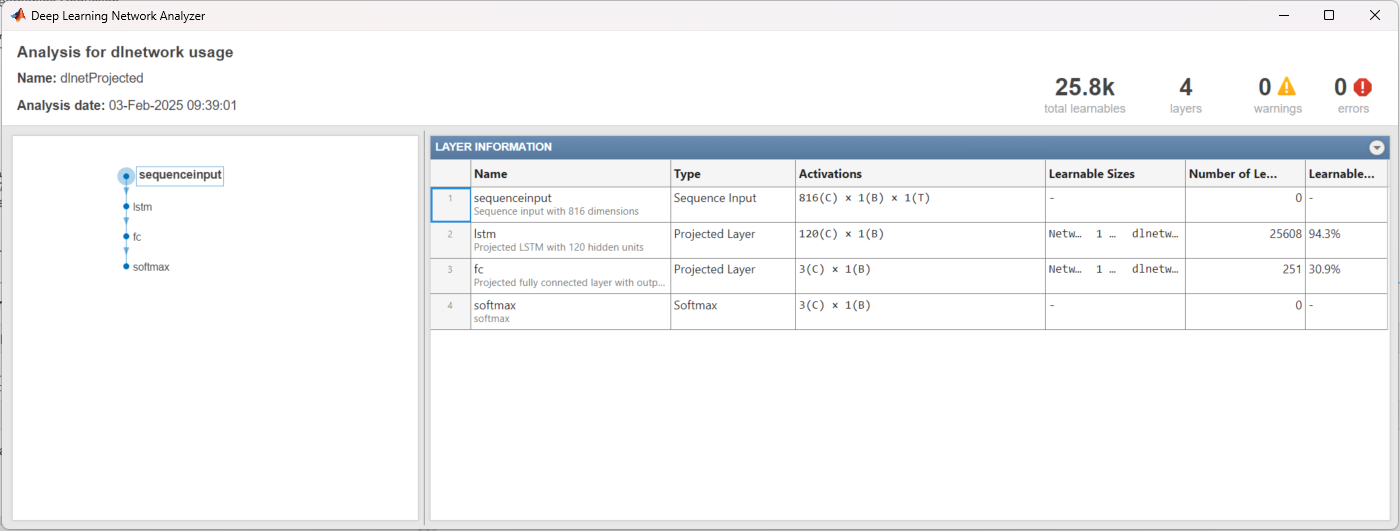

### Fine-tune LSTM Network

Starting with a pretrained network, the projected network equivalent can be directly computed as demonstrated above. Although a high degree of data covariance is retained, the network may need fine-tuning as accuracy can drop following the compression. This could be a result of higher order nonlinear relations between neurons in the network needing to readjust given the linear transformation or a compounding effect if many layers are projected at once. The projected model provides a good initialization for fine-tuning by further retraining. The fine-tune retraining typically takes far fewer epochs for the accuracy to plateau and can largely recover, in many cases, the accuracy of the original network.

doTraining = true; % Set to true if you would like to run fine-tuning, otherwise, the script will load a fine-tuned model from file below

if doTraining

    options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    InitialLearnRate=0.001,...
    LearnRateDropFactor = 0.1,...
    GradientThreshold=1, ...
    Shuffle="never", ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    ValidationFrequency = 10, ...
    ValidationData = {test',categorical(testLabels)},...
    Verbose=false);
   
    LSTMProjected = trainnet(train',categorical(trainLabels),dlnetProjected,"crossentropy",options);
else
    load("projectedLSTM.mat");
end

testnet(LSTMProjected,test',categorical(testLabels),"accuracy")

*Copyright 2024 The MathWorks, Inc.*